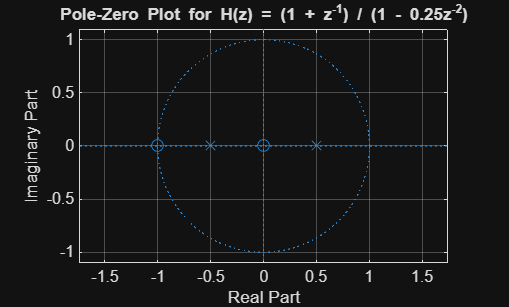

% 9.2c Poles & Zeros
% Define the coefficients of the numerator polynomial (B(z))
% B(z) corresponds to z^2 + z + 0
B = [1, 1, 0];

% Define the coefficients of the denominator polynomial (A(z))
% A(z) corresponds to z^2 + 0*z - 0.25
A = [1, 0, -0.25];

% Plot the pole-zero plot
figure;
zplane(B, A);
title('Pole-Zero Plot for H(z) = (1 + z^{-1}) / (1 - 0.25z^{-2})');
grid on;

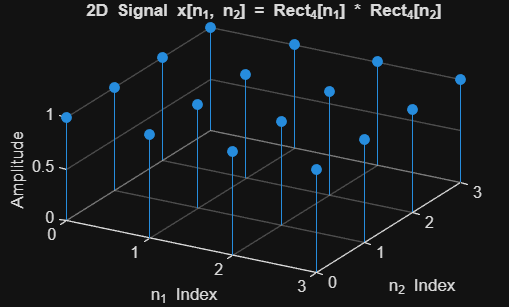

% 1. Define the range for the indices
N = 4;
n = 0:N-1; 

% 2. Create the 2D signal matrix
% The matrix X will be a 4x4 matrix of all ones.
X = ones(N, N); 

% 3. Create the mesh grid (required for 3D plotting)
[n1, n2] = meshgrid(n, n);

% 4. Plot the 2D discrete signal using stem3
figure;
stem3(n1, n2, X, 'filled');
title('2D Signal x[n_1, n_2] = Rect_4[n_1] * Rect_4[n_2]');
xlabel('n_1 Index');
ylabel('n_2 Index');
zlabel('Amplitude');
view(30, 45); % Set viewing angle for better visualization
grid on;